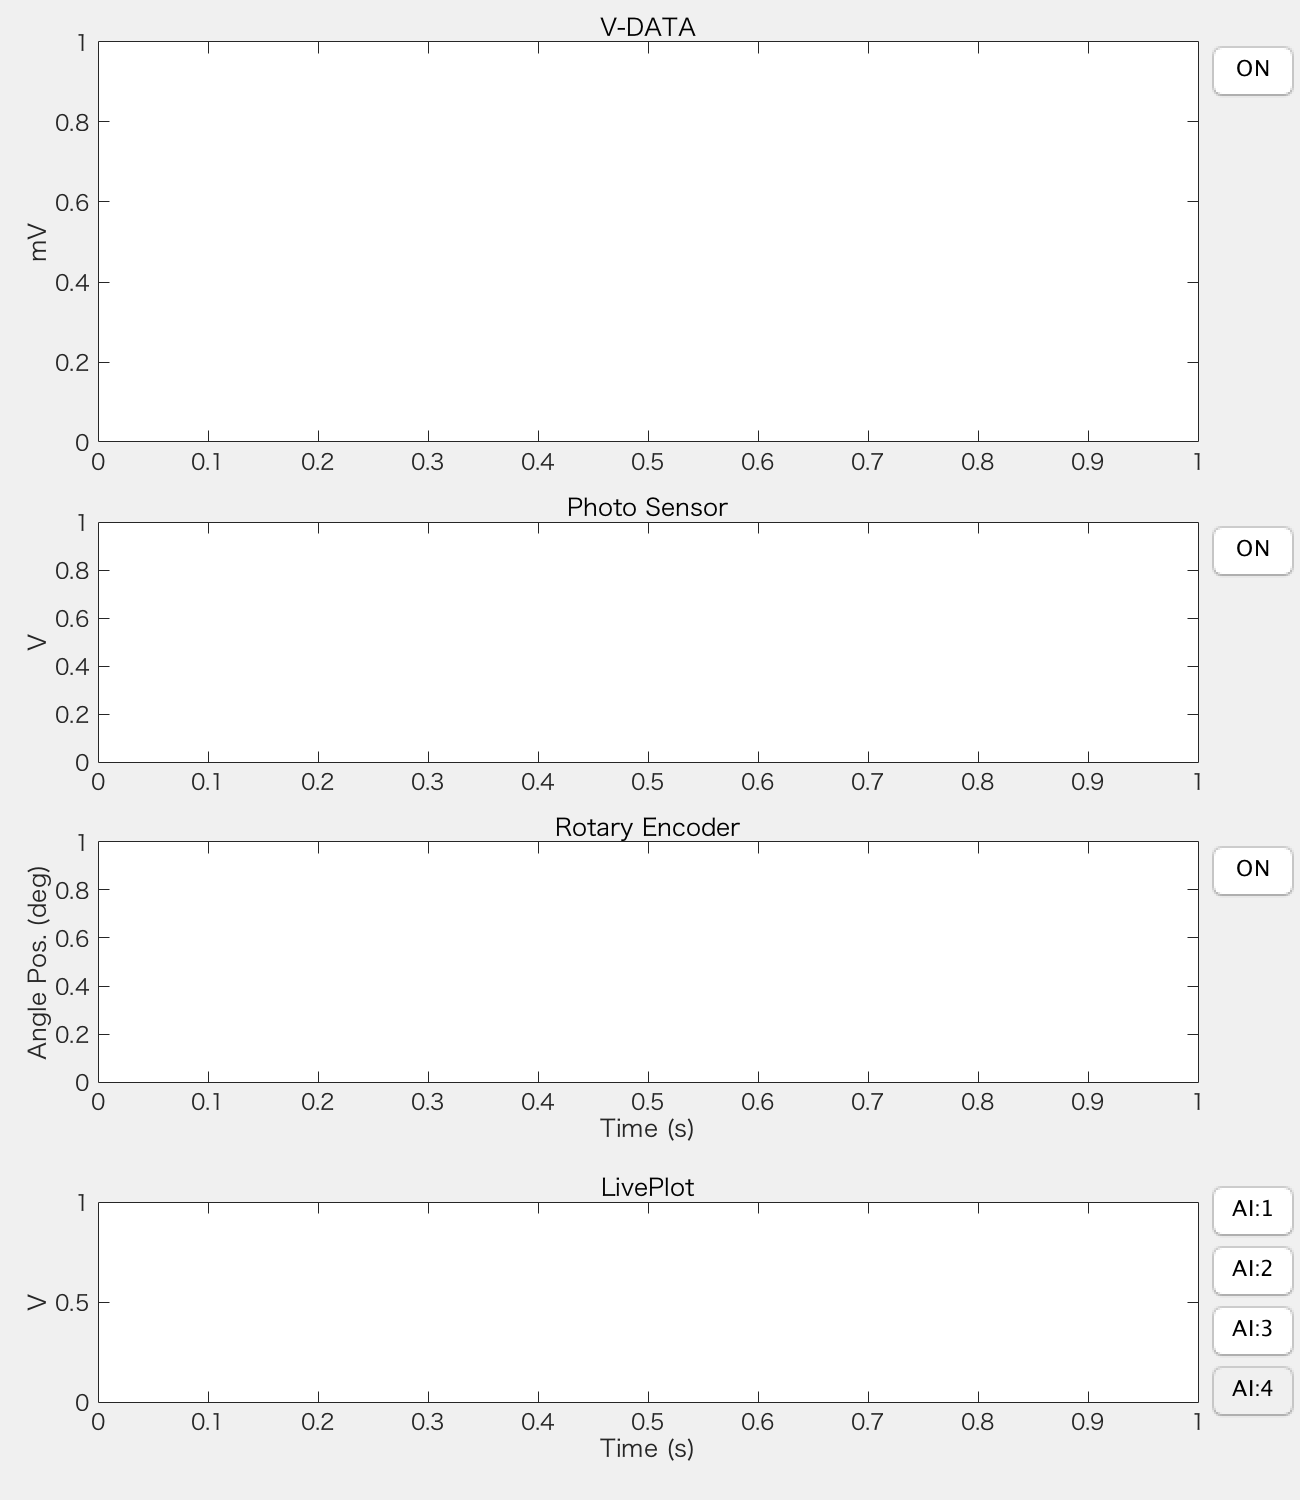

%function hGui = plot_window
%plot_window creates plot window for  None But Air 
% plotUIobj = plot_window

global sobj
global recobj
global s


%% %---------- Create plot window ----------%
%open plot window
hGui.fig = figure('Position',[600, 20, 650, 750], 'Name','Plot Window NBA11', 'NumberTitle', 'off', 'Menubar','none', 'Resize', 'off');

%% Axes, Plot
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%   AI1, AI2 plot    %%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hGui.axes1 = axes('Unit','Pixels', 'Position',[50,530,550,200], 'XLimMode', 'manual','YlimMode', 'Auto');
hGui.plot1 = plot(0, NaN(1,1),'b');
ylabel('mV');
title('V-DATA');

hGui.button1 = uicontrol('style','togglebutton','string', 'ON', 'position',[605 700 45 30],...
    'callback', {@ch_ButtonColor, 'g'}, 'Horizontalalignment','center');
        

%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%   Rotary Encoder   %%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hGui.axes2 = axes('Unit','Pixels', 'Position',[50,370,550,120], 'XLimMode', 'manual','YlimMode', 'Auto');
hGui.plot2 = plot(0, NaN(1,1));
ylabel('V');
title('Photo Sensor');

hGui.button2 = uicontrol('style','togglebutton','string', 'ON', 'position',[605 460 45 30],...
    'callback', {@ch_ButtonColor, 'g'}, 'Horizontalalignment','center');

%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%   Rotary Encoder   %%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hGui.axes3 = axes('Unit','Pixels', 'Position',[50,210,550,120], 'XLimMode', 'manual','YlimMode', 'Auto');
hGui.plot3 = plot(0, NaN(1,1));
xlabel('Time (s)');
ylabel('Angle Pos. (deg)');
title('Rotary Encoder');

hGui.button3 = uicontrol('style','togglebutton','string', 'ON', 'position',[605 300 45 30],...
    'callback', {@ch_ButtonColor, 'g'}, 'Horizontalalignment','center');
%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%   Live Plot TTL   %%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hGui.axes4 = axes('Unit','Pixels', 'Position',[50,50,550,100], 'XLimMode', 'manual','YlimMode', 'Auto');
num_plots = 4;
if num_plots > 1
    hGui.button4 = cell(1, num_plots);
    for ii = 1:num_plots
        hGui.button4{1, ii} = uicontrol('style','togglebutton','string',['AI:',num2str(ii)],'position',[605 130-(30*(ii-1)) 45 30],'Horizontalalignment','center');
        set(hGui.button4{1, ii}, 'callback', {@ch_ButtonColor, 'g'});
        if ii == 4
            set(hGui.button4{1,ii},'value',1, 'BackGroundColor','g')
        end
    end
end
hGui.plot4 = plot(0, NaN(1,num_plots));
xlabel('Time (s)');
ylabel('V');
title('LivePlot');


%%
